s = tf('s');
A = [0 1 0 0; 0 0 -3.2667 0; 0 0 0 1; 0 0 19.6 0]

A =          0    1.0000         0         0
         0         0   -3.2667         0
         0         0         0    1.0000
         0         0   19.6000         0


B = [0 0; 0.8889 -1.333; 0 0; -1.333 8]

B =          0         0
    0.8889   -1.3330
         0         0
   -1.3330    8.0000


C = [1 0 0 0; 0 0 1 0]

C =      1     0     0     0
     0     0     1     0


D = [0 0;0 0];
zpk(minreal(D+C*inv(s * eye(4) - A) * B))

ans =
 
  From input 1 to output...
       0.8889 (s-3.834) (s+3.834)
   1:  --------------------------
        s^2 (s+4.427) (s-4.427)
 
             -1.333
   2:  -------------------
       (s+4.427) (s-4.427)
 
  From input 2 to output...
       -1.333 (s+4.35e-07) (s-4.35e-07) (s^2 - 3.06e-12s + 0.005101)
   1:  -------------------------------------------------------------
                          s^4 (s-4.427) (s+4.427)
 
                8
   2:  -------------------
       (s+4.427) (s-4.427)
 
Continuous-time zero/pole/gain model.



Atilda = [A zeros(4,2); C zeros(2,2)]

Atilda =          0    1.0000         0         0         0         0
         0         0   -3.2667         0         0         0
         0         0         0    1.0000         0         0
         0         0   19.6000         0         0         0
    1.0000         0         0         0         0         0
         0         0    1.0000         0         0         0


Btilda = [B; zeros(2,2)]

Btilda =          0         0
    0.8889   -1.3330
         0         0
   -1.3330    8.0000
         0         0
         0         0


Mc = ctrb(Atilda, Btilda);
rank(Mc)

ans = 6

K = place(Atilda, Btilda, [-20, -20.1, -20.2, -19.9, -19.8, -20.3])

K = 	1.0e+04 *

    0.1808    0.0090    0.0292    0.0015    1.2083    0.1916
    0.0301    0.0015    0.0202    0.0010    0.2006    0.1326


To confirm pole positions

eig(Atilda - Btilda * K)

ans =   -19.8000
  -20.3000
  -19.9000
  -20.0000
  -20.2000
  -20.1000


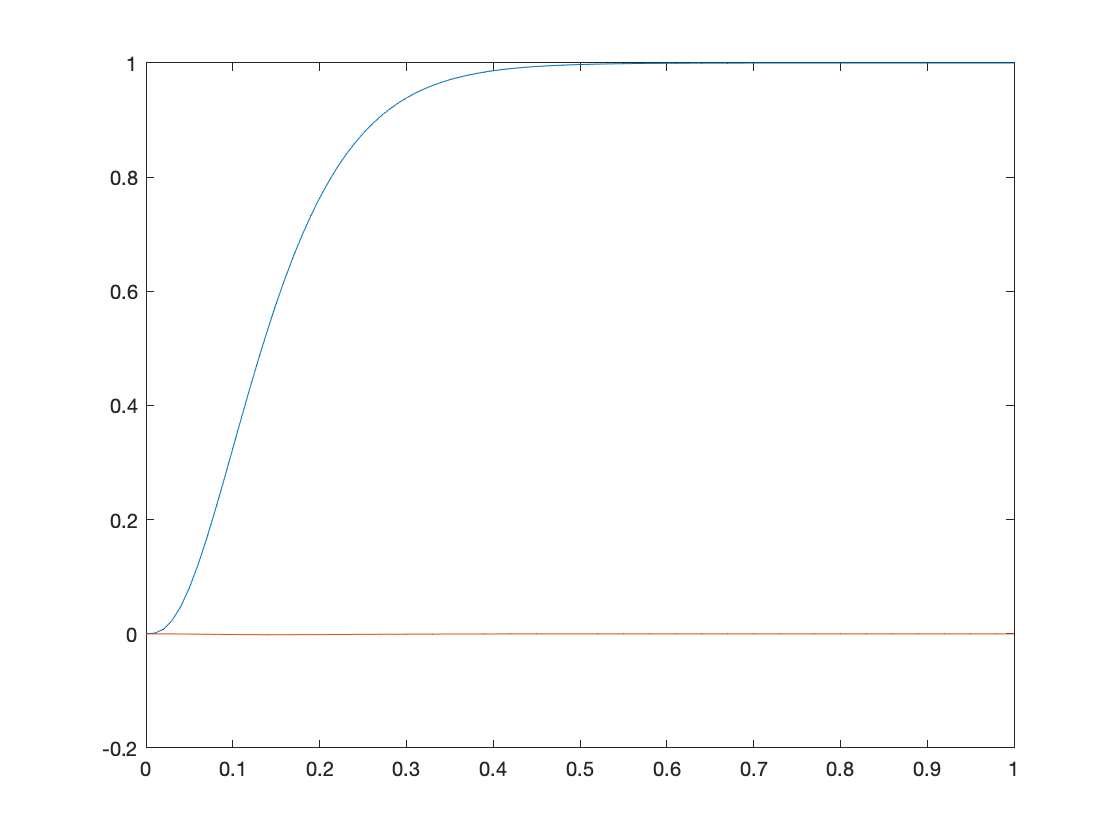

K1 = K(:,1:4);
K2 = K(:,5:end);
A_cls = [A-B*K1 -B*K2; C zeros(2,2)];
% A_cls = Atilda - Btilda * K
B_cls = [zeros(4, 2); -eye(2)];
C_cls = [C zeros(2, 2)];
D_cls= zeros(2,2);
CLS = ss(A_cls, B_cls, C_cls, D_cls);
T = 0:0.01:1;
r_step = ones(1, length(T))';
r_zero = zeros(1, length(T))';
yA = lsim(CLS, [r_step, r_zero], T, [0 0 0 0 0 0]');
figure(3);
plot(T, yA);

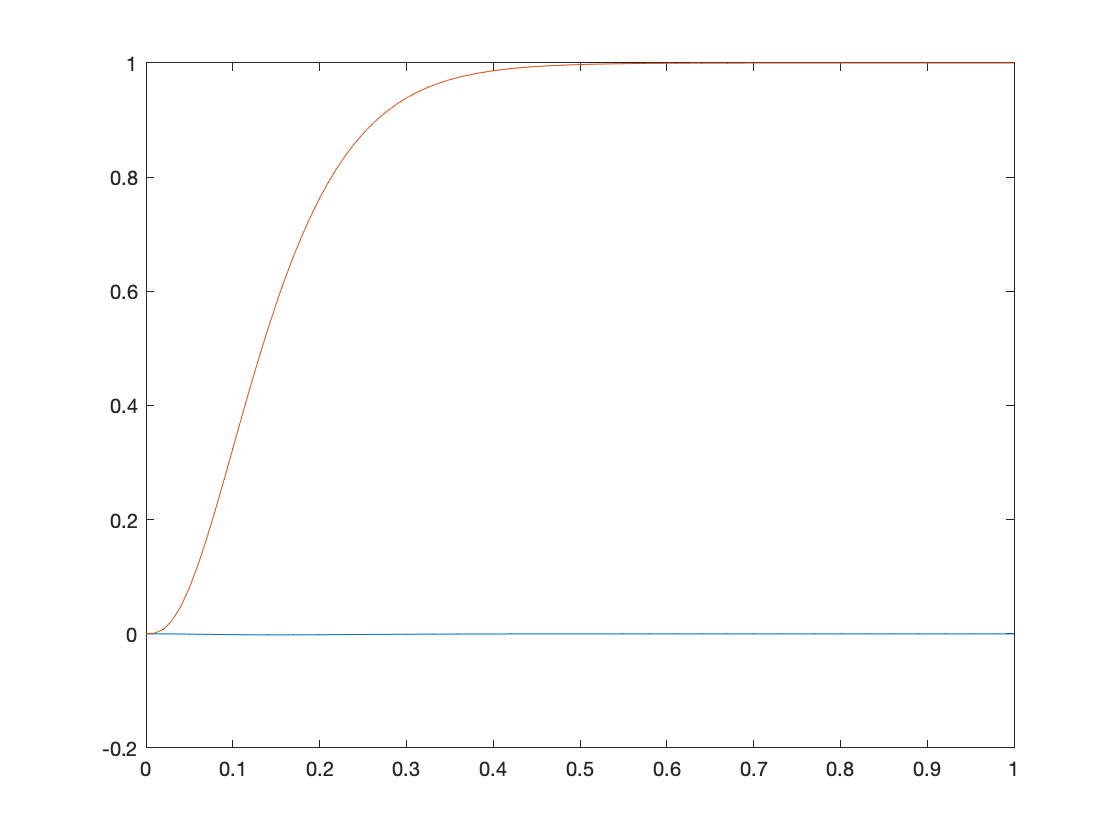

yB = lsim(CLS, [r_zero, r_step], T, [0 0 0 0 0 0]');
plot(T, yB);

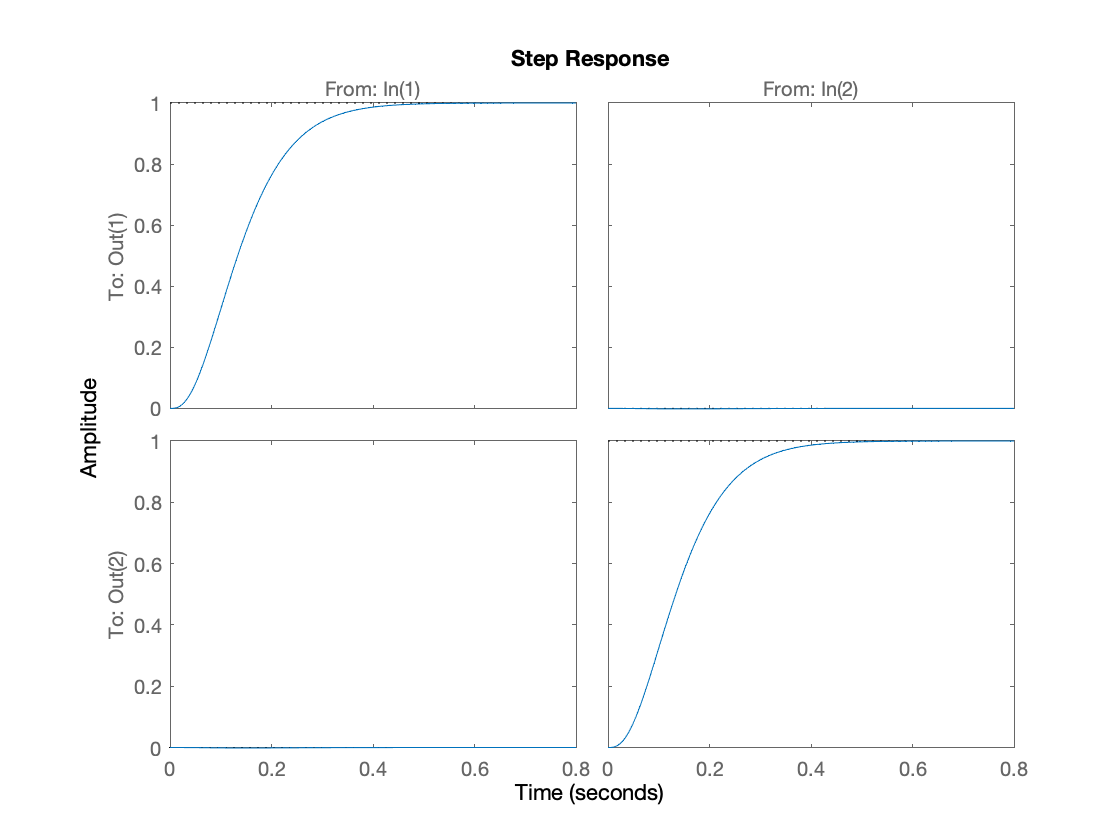

step(CLS)

A_2 = [0 1 0 0 0 0; 0 0 -4.41 0 0.49 0; 0 0 0 1 0 0; 0 0 61.74 0 -26.46 0;0 0 0 0 0 1;0 0 -79.38 0 67.62 0]

A_2 =          0    1.0000         0         0         0         0
         0         0   -4.4100         0    0.4900         0
         0         0         0    1.0000         0         0
         0         0   61.7400         0  -26.4600         0
         0         0         0         0         0    1.0000
         0         0  -79.3800         0   67.6200         0


B_2 = [0 0 0;0.9333 -2.40 0.80;0 0 0;-2.40 33.60 -43.20;0 0 0;0.80 -43.20 110.40]

B_2 =          0         0         0
    0.9333   -2.4000    0.8000
         0         0         0
   -2.4000   33.6000  -43.2000
         0         0         0
    0.8000  -43.2000  110.4000


C_2 = [1 0 0 0 0 0;0 0 1 0 0 0;0 0 0 0 1 0]

C_2 =      1     0     0     0     0     0
     0     0     1     0     0     0
     0     0     0     0     1     0


D_2 = [0 0 0;0 0 0;0 0 0];
zpk(D_2+C_2*inv(s * eye(6) - A_2) * B_2)

ans =
 
  From input 1 to output...
                                                                                                                             
       0.9333 s^2 (s+10.52) (s+10.16) (s+4.331) (s+3.788) (s-4.331) (s-3.788) (s-10.16) (s-10.52) (s+5.209e-08) (s-5.209e-08)
                                                                                                                             
                                                                                                                             
   1:  ----------------------------------------------------------------------------------------------------------------------
                                                                                                         
                          s^4 (s+10.52)^2 (s+4.331)^2 (s-10.52)^2 (s-4.331)^2 (s+5.342e-08) (s-5.342e-08)
                                                                                                         
 
       -2.4 (s

Atilda_2 = [A_2 zeros(6,3); C_2 zeros(3,3)];
Btilda_2 = [B_2; zeros(3,3)]

Btilda_2 =          0         0         0
    0.9333   -2.4000    0.8000
         0         0         0
   -2.4000   33.6000  -43.2000
         0         0         0
    0.8000  -43.2000  110.4000
         0         0         0
         0         0         0
         0         0         0


Mc_2 = ctrb(Atilda_2, Btilda_2);
rank(Mc_2)

ans = 9

K_2 = place(Atilda_2, Btilda_2, [-20, -20.1, -20.2, -19.9, -19.8, -20.3, -19.7, -20.4, -20.5])

K_2 = 	1.0e+04 *

    0.1815    0.0090    0.0222    0.0011    0.0076    0.0004    1.2146    0.1474    0.0509
    0.0227    0.0011    0.0102    0.0005    0.0038    0.0002    0.1516    0.0667    0.0251
    0.0075    0.0004    0.0038    0.0002    0.0026    0.0001    0.0505    0.0250    0.0168


eig(Atilda_2 - Btilda_2 * K_2)

ans =   -19.7000
  -20.5000
  -19.8000
  -19.9000
  -20.4000
  -20.3000
  -20.0000
  -20.1000
  -20.2000


To confirm pole positions

A_cls2 = Atilda_2 - Btilda_2 * K_2;
B_cls2 = [zeros(6, 3); -eye(3)];
C_cls2 = [C_2 zeros(3,3)];
D_cls2 = 0;
CLS_2 = ss(A_cls2, B_cls2, C_cls2, D_cls2);
T_2 = 0:0.01:1;
r_step_2 = ones(1, length(T_2))';
r_zero_2 = zeros(1, length(T_2))';
x_o = [0,0,0,0,0,0,0,0,0]

x_o =      0     0     0     0     0     0     0     0     0


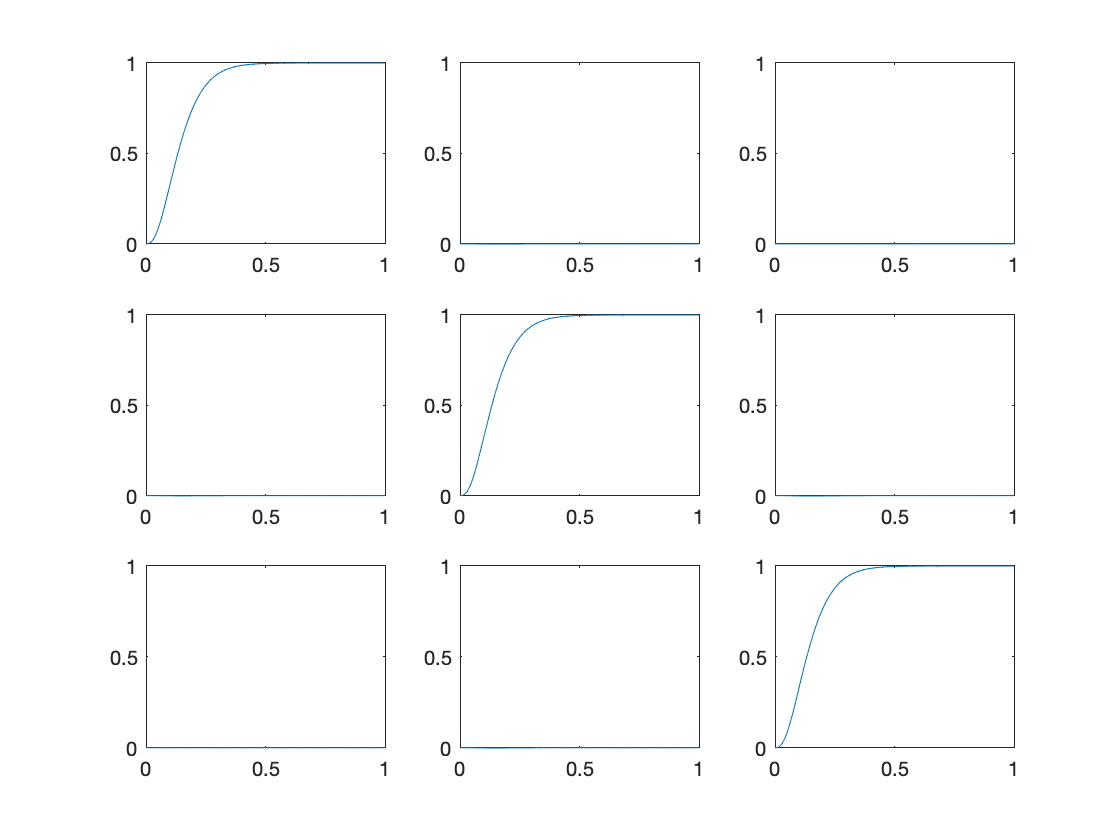


% step(CLS_2);
yA_2 = lsim(CLS_2, [r_step_2, r_zero_2, r_zero_2], T_2, x_o');
yB_2 = lsim(CLS_2, [r_zero_2, r_step_2, r_zero_2], T_2, x_o');
yC_2 = lsim(CLS_2, [r_zero_2, r_zero_2, r_step_2], T_2, x_o');
t_ = tiledlayout(3,3);
figure(1);
ax1 = subplot(3,3,1);
plot(T,yA_2(:,1));
ax2 = subplot(3,3,2);
plot(T,yB_2(:,1));
ax3 = subplot(3,3,3);
plot(T,yC_2(:,1));

ax4 = subplot(3,3,4);
plot(T,yA_2(:,2));
ax5 = subplot(3,3,5);
plot(T,yB_2(:,2));
ax6 = subplot(3,3,6);
plot(T,yC_2(:,2));

ax7 = subplot(3,3,7);
plot(T,yA_2(:,3));
ax8 = subplot(3,3,8);
plot(T,yB_2(:,3));
ax9 = subplot(3,3,9);
plot(T,yC_2(:,3));
linkaxes([ax1,ax2,ax3],'y');
linkaxes([ax4,ax5,ax6],'y');
linkaxes([ax7,ax8,ax9],'y');

rank(obsv(A_2,C_2))

ans = 6

H = place(A_2', C_2', [-40, -40.01, -40.02, -40.03, -39.99, -39.98])';
K1_2 = K_2(:, 1:6)

K1_2 = 	1.0e+03 *

    1.8147    0.0904    0.2224    0.0112    0.0759    0.0038
    0.2266    0.0113    0.1019    0.0050    0.0376    0.0019
    0.0755    0.0038    0.0375    0.0019    0.0258    0.0013


K2_2 = K_2(:,7:end)

K2_2 = 	1.0e+04 *

    1.2146    0.1474    0.0509
    0.1516    0.0667    0.0251
    0.0505    0.0250    0.0168


Acl = [A_2-B_2*K1_2 -B_2*K2_2 B_2*K1_2; C_2 zeros(3, 3) zeros(3, 6); zeros(6,6) zeros(6,3) A_2-H*C_2];
Bcl = [zeros(6,3); -eye(3); zeros(6,3)];
Ccl = [C_2 zeros(3,3) zeros(3,6)];
Dcl = zeros(3,3);
cls_sf = ss(Acl, Bcl, Ccl, Dcl);
x_oob = [0,0,0,0,0,0,0,0,0,.1,.1,.1,.1,.1,.1]

x_oob =          0         0         0         0         0         0         0         0         0    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000


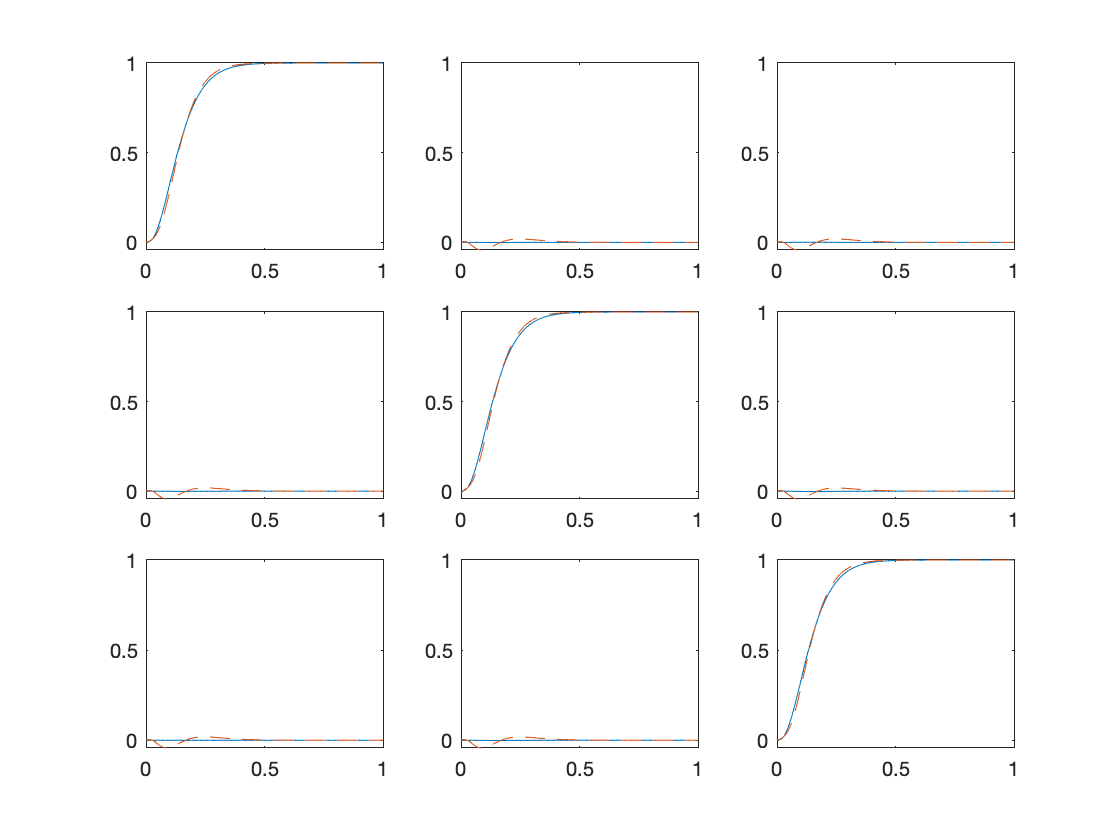

yA_ob = lsim(cls_sf, [r_step_2, r_zero_2, r_zero_2], T_2, x_oob');
yB_ob = lsim(cls_sf, [r_zero_2, r_step_2, r_zero_2], T_2, x_oob');
yC_ob = lsim(cls_sf, [r_zero_2, r_zero_2, r_step_2], T_2, x_oob');
t = tiledlayout(3,3);
figure(2);
ax1 = nexttile;
plot(T,yA_2(:,1), '-', T_2, yA_ob(:,1), '--');
ax2 = nexttile;
plot(T,yB_2(:,1), '-', T_2, yB_ob(:,1), '--');
ax3 = nexttile;
plot(T,yC_2(:,1), '-', T_2, yC_ob(:,1), '--');

ax4 = nexttile;
plot(T,yA_2(:,2), '-', T_2, yA_ob(:,2), '--');
ax5 = nexttile;
plot(T,yB_2(:,2), '-', T_2, yB_ob(:,2), '--');
ax6 = nexttile;
plot(T,yC_2(:,2), '-', T_2, yC_ob(:,2), '--');

ax7 = nexttile;
plot(T,yA_2(:,3), '-', T_2, yA_ob(:,3), '--');
ax8 = nexttile;
plot(T,yB_2(:,3), '-', T_2, yB_ob(:,3), '--');
ax9 = nexttile;
plot(T,yC_2(:,3), '-', T_2, yC_ob(:,3), '--');
linkaxes([ax1,ax2,ax3],'y');
linkaxes([ax4,ax5,ax6],'y');
linkaxes([ax7,ax8,ax9],'y');